# Motor

clear;
close all;

param.motor.efficiency = 0.97; %- given
param.motor.p0 = 30; %W taken from winning solar car
param.motor.maxPower = 5000; %W given

% Motor data obtained using
% https://apps.automeris.io/wpd/
% on the datasheet
torque = readmatrix("torque.csv");
rotationalSpeed = readmatrix("rotationalSpeed.csv");
efficiency = readmatrix("efficiency.csv");

Curve fitting using cftool

torqueXcurrent = torque(:,1);
torqueY = torque(:,2);

rotationalSpeedXcurrent = rotationalSpeed(:,1);
rotationalSpeedY = rotationalSpeed(:,2);

efficiencyXcurrent = efficiency(:,1);
efficiencyY = efficiency(:,2);

%f(x) with x = current
torqueFit = @(x) -4.925*x + 825.3;
rotationalSpeedFit = @(x) 1.159*x - 1.44; %rpm
efficiencyFit = @(x) -76.41/x + 99.38;

Relevant values for power

voltage = 96; %V
maxCurrent = param.motor.maxPower / voltage; %A
current = linspace(1, maxCurrent, floor(maxCurrent)); %A
elPower = voltage * current; %W

mechPower = torqueFit(current) .* rotationalSpeedFit(current)*2*pi/60; %W

Estimation of P0

P0 = interp1(mechPower, elPower, 0);
fprintf('Estimated value from datasheet: P0 = %.3f W', P0)

Estimated value from datasheet: P0 = 119.382 W

Linear least squares

A = elPower';
b = mechPower';
lsqrResult = lsqr(A, b);

lsqr converged at iteration 1 to a solution with relative residual 0.064.


fprintf('Estimated value with LSQR: e = %.3f', lsqrResult)

Estimated value with LSQR: e = 0.769

leastSquareCurve = @(x) lsqrResult(1) * x - P0 * lsqrResult(1);

mechPowerWillanModel = @(x) param.motor.efficiency * x - param.motor.p0;

Plot

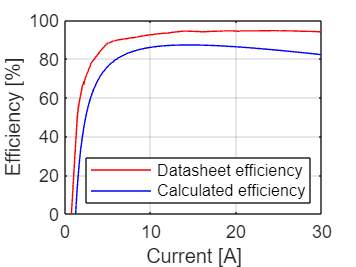

figure
plot(efficiencyXcurrent, efficiencyY,'r','DisplayName','Datasheet efficiency')
hold on
eff = (torqueFit(efficiencyXcurrent) .* rotationalSpeedFit(efficiencyXcurrent)*2*pi/60) ./ (efficiencyXcurrent .* voltage);
plot(efficiency(:,1), eff*100,'b','DisplayName','Calculated efficiency')
legend('Location','southeast')
xlabel("Current [A]")
ylabel("Efficiency [%]")
xlim([0 30])
ylim([0 100])
grid on
box on

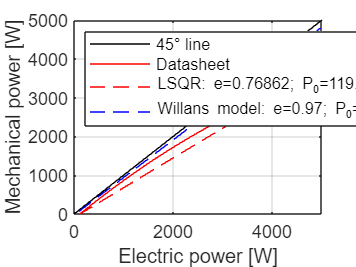

% 
% figure
% plot(rotationalSpeed(:,1), rotationalSpeed(:,2))
% 
% figure
% plot(torque(:,1), torque(:,2))

figure
plot([0 param.motor.maxPower], [0 param.motor.maxPower],'k','DisplayName','45° line')
hold on
plot(elPower, mechPower,'r','DisplayName','Datasheet')
plot(elPower, leastSquareCurve(elPower),'--r','DisplayName',['LSQR: e=',char(num2str(lsqrResult)),'; P_0=',char(num2str(P0)), ' W'])
plot(elPower, mechPowerWillanModel(elPower),'--b','DisplayName',['Willans model: e=',char(num2str(param.motor.efficiency)),'; P_0=',char(num2str(param.motor.p0)), ' W'])
legend('Location','northwest')
xlabel("Electric power [W]")
ylabel("Mechanical power [W]")
xlim([0 param.motor.maxPower])
ylim([0 param.motor.maxPower])
grid on
box on